filename = 'NonInstrumental-SPE-03-30-2020(01)';
load([filename,'_D.mat']);

Calculate lick probability by condition(i.e. reward size)

align by reward delivery which is 3 seconds after fixation initiation

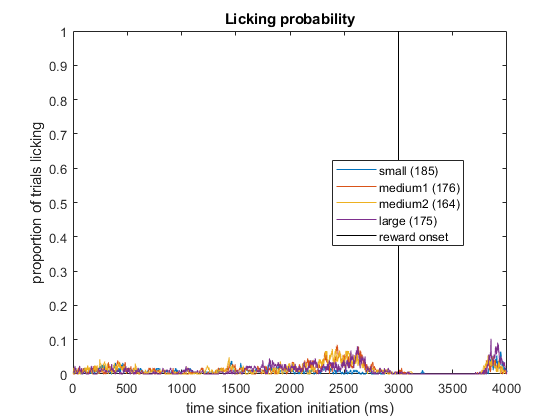

T = 4001;
lickProbability = zeros(4,T); % first count by condition/cue identity
trialCount = zeros(4,1);

for trind = 1:length(D.TrialNumber)
    if ~D.Rewarded(trind) % rewarded/successful trials only
        continue;
    end
    if D.PotentialLickProblem(trind) 
        continue; % exclude trials with lickometer problem
    end
    if strcmp(D.CueName{trind},'stimA') 
        cond = 1;
    elseif strcmp(D.CueName{trind},'stimB1') 
        cond = 2;
    elseif strcmp(D.CueName{trind},'stimB2') 
        cond = 3;
    else
        cond = 4;
    end
    trialCount(cond) = trialCount(cond) + 1;
    RewardOn = D.RewardOnTime(trind);
    lickingBinary = D.LickingBinary{trind};
    lickProbability(cond,:) = lickProbability(cond,:) ...
        + double(lickingBinary((RewardOn-3000):(RewardOn+1000)))';
end

for cind = 1:4
    lickProbability(cind,:) = lickProbability(cind,:) ...
        / trialCount(cind);
end

figure;
for cind = 1:4
    plot(0:4000,lickProbability(cind,:)); hold on;
end
xlabel('time since fixation initiation (ms)');
ylabel('proportion of trials licking')
line([3000,3000],[0,1],'color','k');
legend({['small (' num2str(trialCount(1)) ')'],...
    ['medium1 (' num2str(trialCount(2)) ')'],...
    ['medium2 (' num2str(trialCount(3)) ')'],...
    ['large (' num2str(trialCount(4)) ')'],'reward onset'},'location','best');
title('Licking probability')
saveas(gcf,['licking_probability',filename(find(filename=='-',1):end),'.png']);